clock_freq = 400*10^(6);
clk_period = 1/clock_freq

clk_period = 2.5000e-09

clk_rate = clk_period/2

clk_rate = 1.2500e-09

pancham_cycles = 67;
num_passwords = 14776336;
num_supervisors = [1 , 2, 4, 8, 16, 32, 64, 128]

num_supervisors =      1     2     4     8    16    32    64   128


sec_per_hash = pancham_cycles*clk_period

sec_per_hash = 1.6750e-07

 hash_per_nsec= 1/sec_per_hash*num_supervisors*10^(-9)

hash_per_nsec =     0.0060    0.0119    0.0239    0.0478    0.0955    0.1910    0.3821    0.7642


nsec_per_supervisor = 1./hash_per_nsec

nsec_per_supervisor =   167.5000   83.7500   41.8750   20.9375   10.4688    5.2344    2.6172    1.3086


worst_case_time = sec_per_hash*num_passwords./num_supervisors

worst_case_time =     2.4750    1.2375    0.6188    0.3094    0.1547    0.0773    0.0387    0.0193


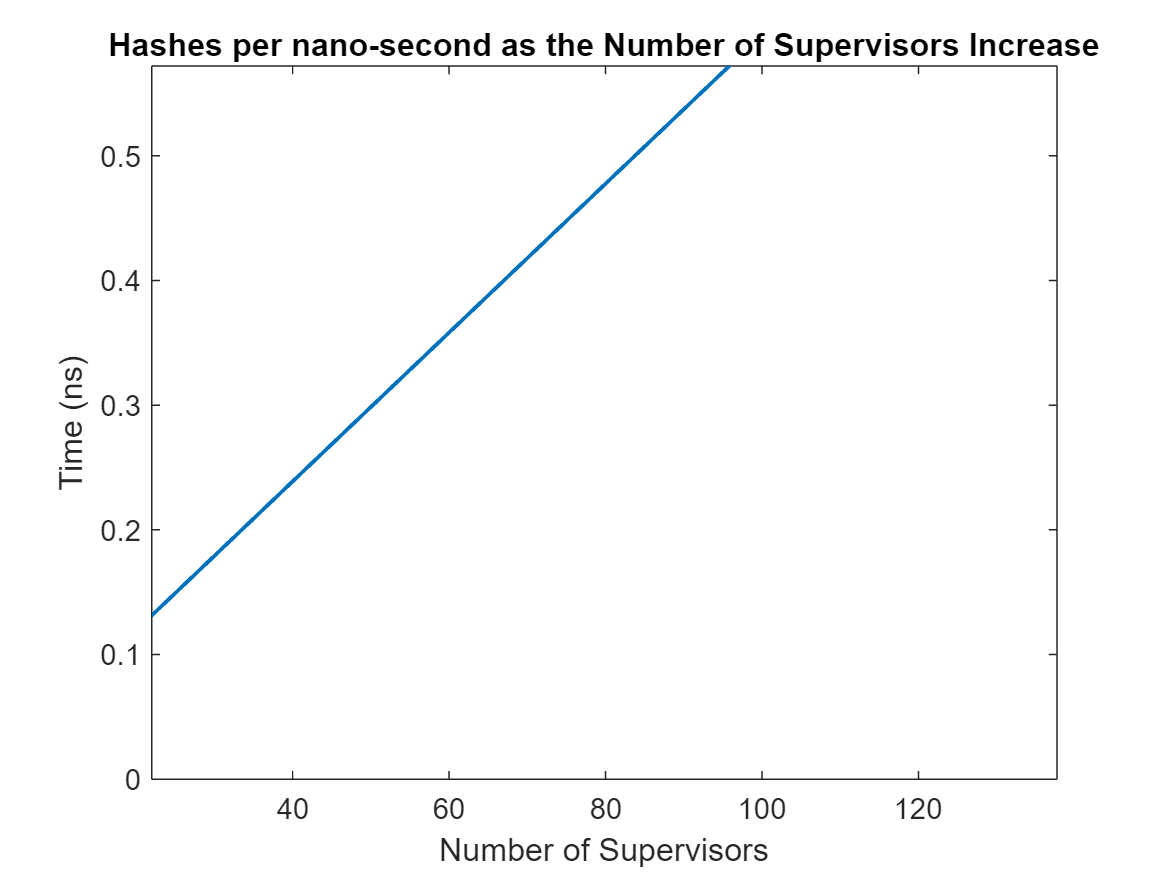

plot(num_supervisors, hash_per_nsec, LineWidth=1.3);
hold on
title 'Hashes per nano-second as the Number of Supervisors Increase'
hold off

xlabel("Number of Supervisors")
ylabel("Time (ns)")

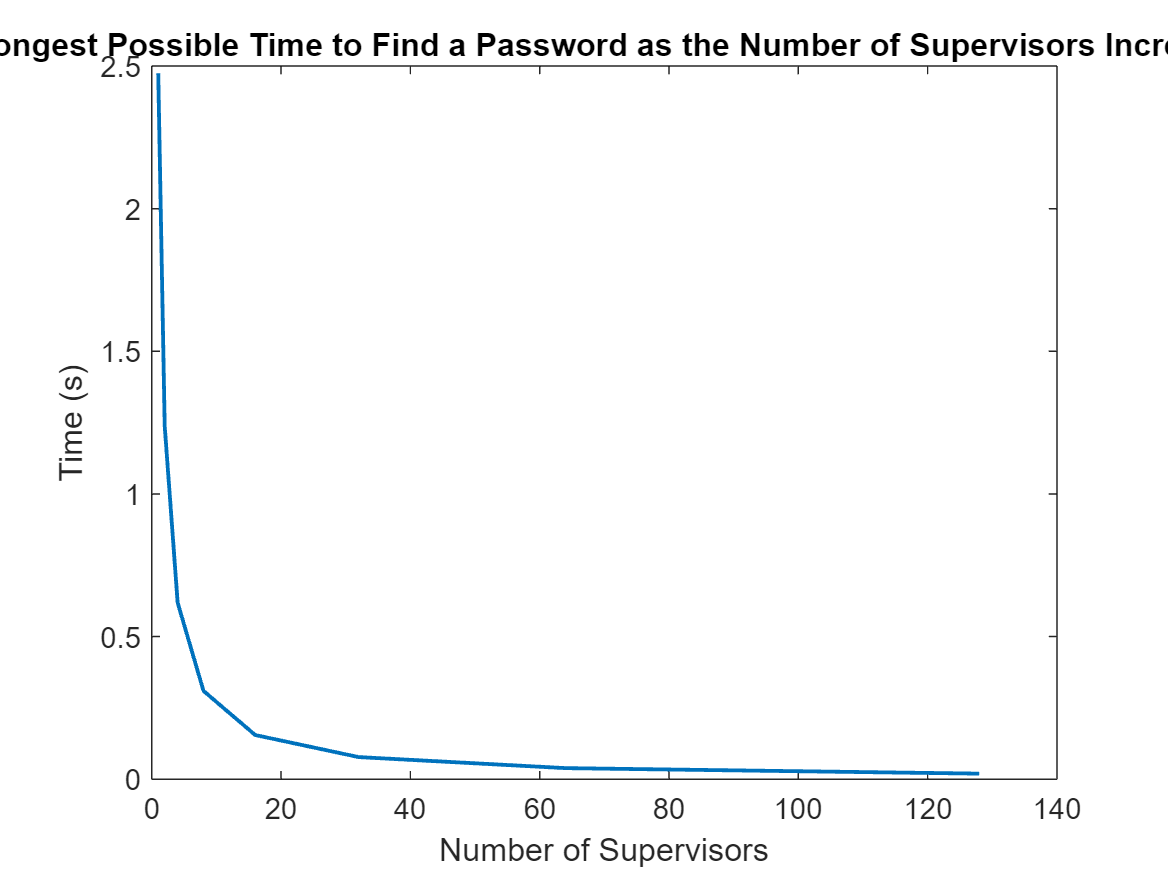


plot(num_supervisors,worst_case_time, LineWidth=1.3);
hold on
title 'Longest Possible Time to Find a Password as the Number of Supervisors Increase'
hold off

xlabel("Number of Supervisors")
ylabel("Time (s)")

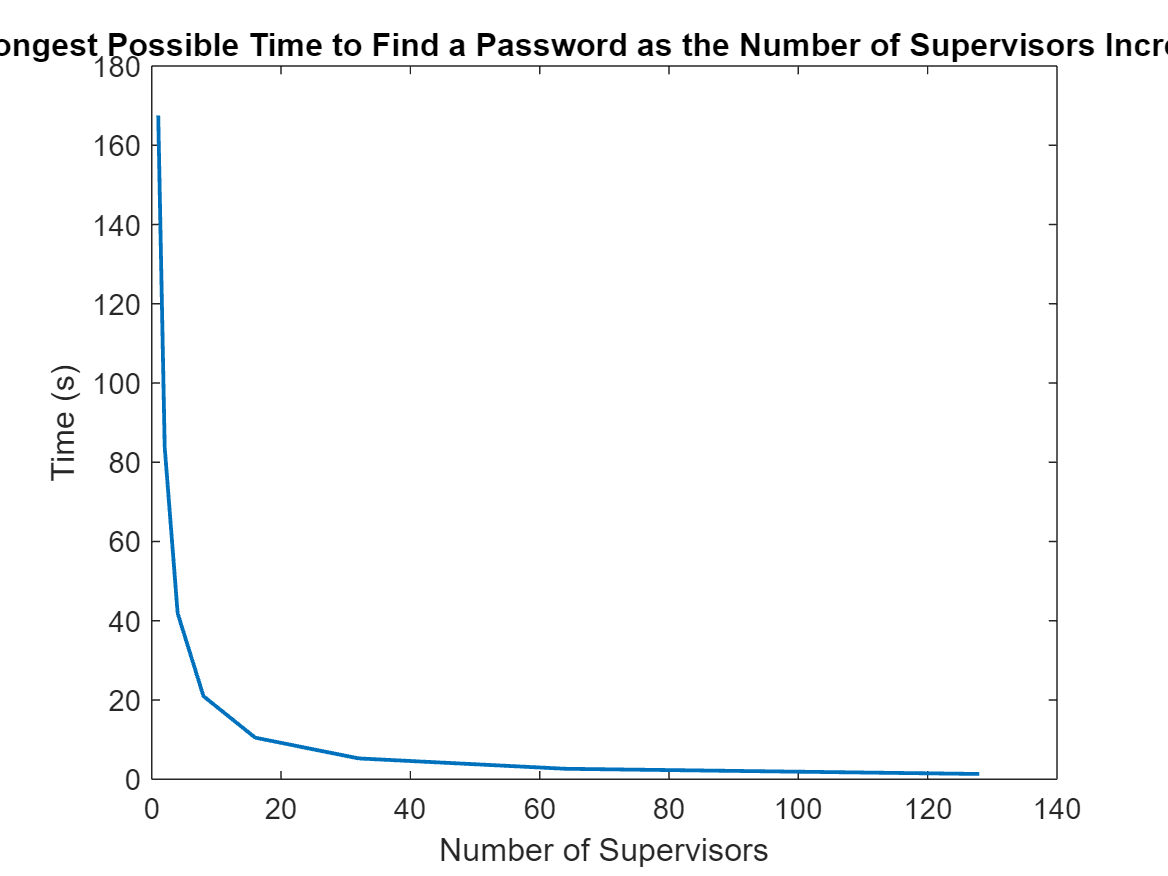


plot(num_supervisors,nsec_per_supervisor, LineWidth=1.3);
hold on
title 'Longest Possible Time to Find a Password as the Number of Supervisors Increase'
hold off

xlabel("Number of Supervisors")
ylabel("Time (s)")

brute_force_time = num_passwords/9.4292;
longest_time = worst_case_time(1)

longest_time = 2.4750

prev_speed_up = [1.2375]

speed_up =      1     2     4     8    16    32    64   128


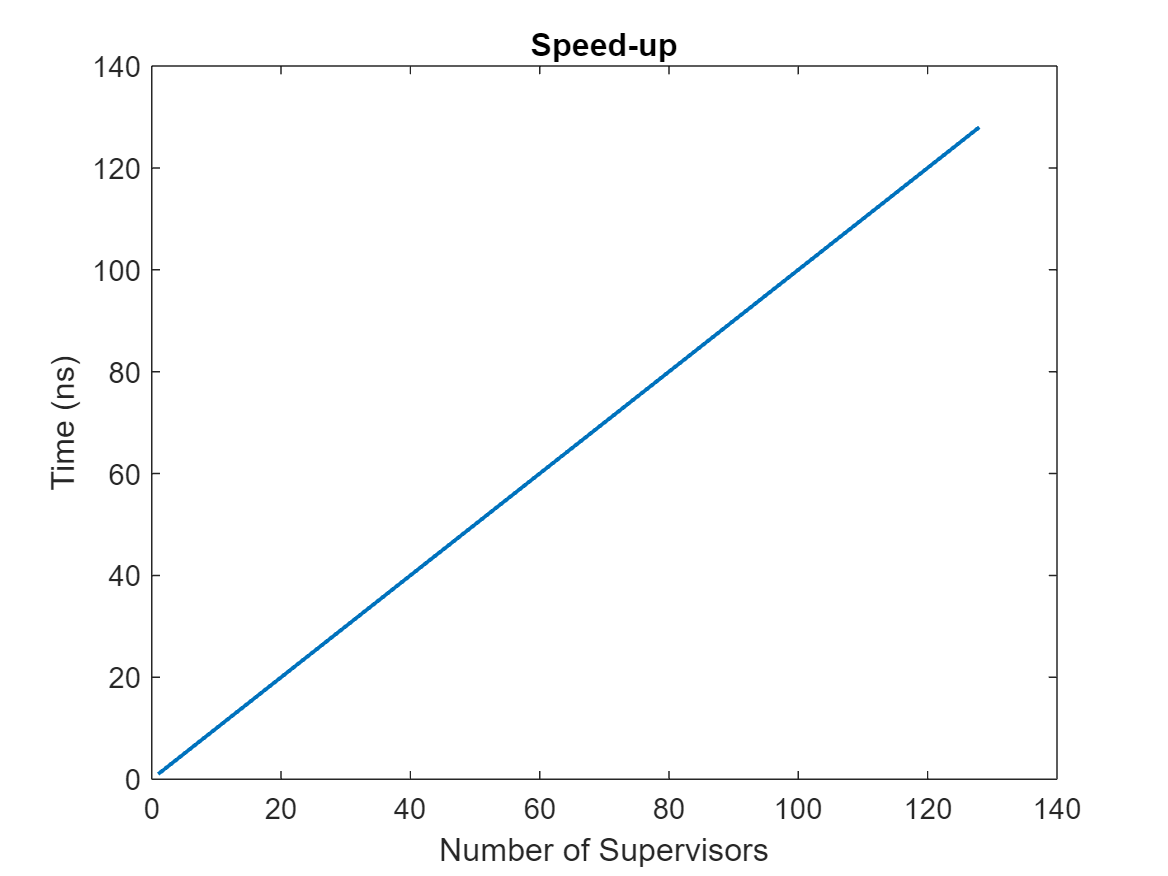


plot(num_supervisors, speed_up, LineWidth=1.3);
hold on
title 'Speed-up'
hold off

xlabel("Number of Supervisors")
ylabel("Time (ns)")